%%% Question 1 %%%%
N = 500; R = 0.001; L = 2; T = 300;        % Declare number of particles, radius of particles, and space length (L x L x L)
% Setting T = 2.0 K for now
sigma = 0.01; epsilon  = 0.1;                    % Cutoff distance, well depth
iterations = 100;                            % Setting iterations as 10 times for now    
rho_temp = N/(L^3); 
[pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, T, sigma, epsilon, iterations, rho_temp);

T = 2

rho = 0.1000

rand
    "1"    "vs"    "0.31318"

rand
    "1"    "vs"    "0.85103"

rand
    "1"    "vs"    "0.42193"

rand
    "1"    "vs"    "0.42037"

rand
    "1"    "vs"    "0.74358"

rand
    "1"    "vs"    "0.28586"

rand
    "1"    "vs"    "0.42477"

rand
    "1"    "vs"    "0.35696"

rand
    "1"    "vs"    "0.29656"

rand
    "1"    "vs"    "0.27528"

rand
    "1"    "vs"    "0.61775"

rand
    "1"    "vs"    "0.017279"

rand
    "1"    "vs"    "0.12411"

rand
    "1"    "vs"    "0.282"

rand
    "1"    "vs"    "0.43689"

rand
    "1"    "vs"    "0.84542"

rand
    "1"    "vs"    "0.60417"

rand
    "1"    "vs"    "0.28675"

rand
    "1"    "vs"    "0.12561"

rand
    "1"    "vs"    "0.10164"

rand
    "1"    "vs"    "0.010916"

rand
    "1"    "vs"    "0.59616"

rand
    "1"    "vs"    "0.51577"

rand
    "1"    "vs"    "0.87505"

rand
    "1"    "vs"    "0.2155"

rand
    "1"    "vs"    "0.15185"

rand
    "1"    "vs"    "0.058916"

rand
    "1"    "vs"    "0.996"

rand
    "1"    "vs"  

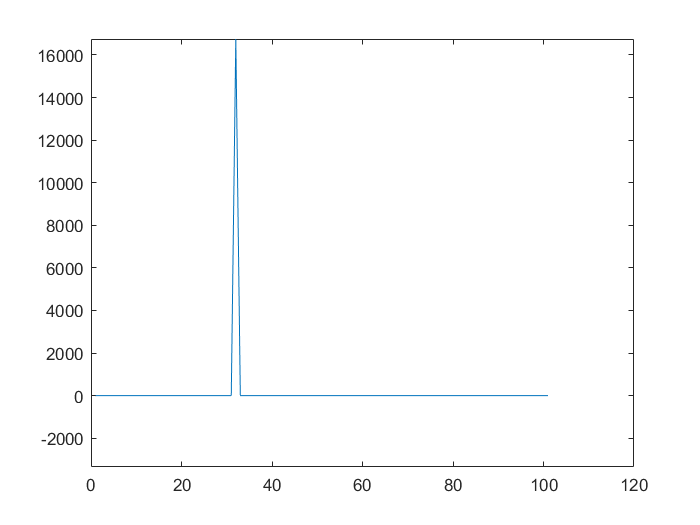

Unrecognized function or variable 'Pavg'.

%%% Question 2 %%%
rho_2 = [0.1:0.1:1];
T_2 = [2,0.9];
P_rho = [];
for i = 1:length(T_2)
    T = T_2(i)
    for j = 1:length(rho_2)
        rho = rho_2(j)
        [pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, T, sigma, epsilon, iterations, rho_temp);
        P_avg = mean(P_hist); 
        P_rho = [P_rho, P_avg];
        %run monte carlo code, extract P(rho) and store in a matrix  
        j = j+1
    end
    %store matrix from inner for loop as variable for that temperature
    %(should end up with two)
    subplot(1, 2, i); 
    plot(rho_2, P_rho); 
    i = i+1
end

% plot P(rho) for T_2[1]
% plot P(rho) for T_2[2]
%answer: for which densities and temperatures you observe phase separation?